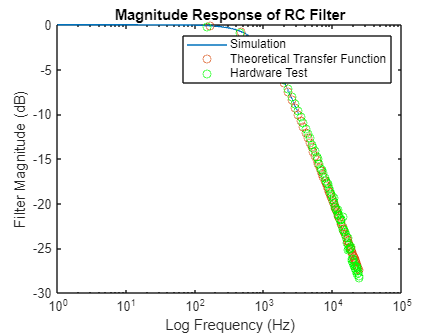

%Lab 3
R = 15e3;
C = 10e-9;
TheoryFreq = linspace(0, 3200, 3200);
TheoryMag = 20*log10(abs (1./(1+j*2*pi*R*C*TheoryFreq)));

semilogx (TheoryFreq, TheoryMag);
hold on;
semilogx(SimFreq, SimMag, 'o');
semilogx(PhysFreq, PhysMag, 'o', 'Color','green');
title('Magnitude Response of RC Filter');
xlabel('Log Frequency (Hz)');
ylabel('Filter Magnitude (dB)');
legend('Simulation', 'Theoretical Transfer Function', 'Hardware Test');